# **CONTROLADORES PID**

**zn en lazo cerrado**

%clear all
clc;
s=tf('s');
%Funciones de transferencia para prueba
disp('Funcion de Tranferencia')

Funcion de Tranferencia


%Gs=zpk([],[-1 -1 -1],1)    %Sistema con 3 polos reales
Gs=1/(s*(s+1)*(s+2))        %Sistema tipo 1 , tiene un polo en el origen

Gs =
 
          1
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.



%Gs=4/(s*(s+1)*(s+5))       %Sistema tipo 1 , tiene un polo en el origen
%Gs=400/(s*(s^2+30*s+1))    %Sistema tipo 1 , tiene un polo en el origen
%Gs=1/((1.25*s+1)*(s+1)*(4*s+1))
[Kcr,~,Wcr,~]=margin(Gs);    %Aqui hallamos el valor de k critico y Wcr para P critico
disp('Aqui tenemos los valores de K critica y P critica')

Aqui tenemos los valores de K critica y P critica


Kcr=Kcr

Kcr = 6.0000

Pcr=2*pi/Wcr                %Formula para P critico

Pcr = 4.4429


%PARA CONTROLADOR P

Kp=0.5*Kcr;
disp('Controlador Proporcional')

Controlador Proporcional


C1=tf(Kp,1)

C1 =
 
  3
 
Static gain.



T1=feedback(Gs*C1,1);

%PARA CONTROLADOR PI

Kp1=0.45*Kcr; Ti1=Pcr/1.2;
disp('Controlador PI')

Controlador PI


C2=Kp1*(1+1/(Ti1*s))

C2 =
 
  9.996 s + 2.7
  -------------
     3.702 s
 
Continuous-time transfer function.



T2=feedback(Gs*C2,1);

%PARA CONTROLADOR PID

Kp2=0.6*Kcr; Ti2=0.5*Pcr; Td=0.125*Pcr;
disp('Controlador PID')

Controlador PID


C3=Kp2*(1+1/(Ti2*s)+Td*s)

C3 =
 
  4.441 s^2 + 7.997 s + 3.6
  -------------------------
           2.221 s
 
Continuous-time transfer function.



T3=feedback(Gs*C3,1);

%Validacion de los 3 controladores 
disp('Validacion de los 3 compensadores')

Validacion de los 3 compensadores


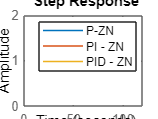

step(T1,T2,T3)
legend('P-ZN','PI - ZN','PID - ZN');